# Supervised Learning - Week 3 / Part 3

## Simplified Cost Function

In the previous file we saw the loss function and the cost function for the logistic regression. In this file we will see a simpler way to write the loss and cost functions for a logistic regression task. Therefore, the implementation will be simpler when we need to implement logistic regression using gradient descent (GD).

As a reminder, the following is the loss function for the logistic regression,


$$L\left( y^{(i)}, f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right) = 
\left\{
    \begin{array}{lr}
        -\log\left( f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right), & \text{if } y^{(i)} = 1  \\
        -\log\left( 1 - f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right), & \text{if } y^{(i)} = 0
    \end{array}$$


Since $y$ can only take the values 0 or 1 and nothing else, we will be able to come up with a simpler expression. We can write the loss function as follows:


$$L\left( y^{(i)}, f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) = -(1-y^{(i)}) \log \left( 1 - f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) - y^{(i)}\log \left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right)$$


Using the simplified loss function definition above, we can write a simplified cost function expression as follows:


$$J(\mathbf{w},b) = \frac{1}{m} \sum_{i=1}^{m} L \left( f_{\mathbf{w},b} (\mathbf{x}^{(i)}), y^{(i)}  \right) = -\frac{1}{m} \sum_{i=1}^{m} \bigg( \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) + y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg)$$


An important question this point is that "Why did we chose this particular loss function, where there are plenty of other alternative loss functions out there?"

This particular loss function is derived using **maximum likelihood estimation (MLE)**. Also, this cost function has good properties of being convex, which is crucial for the GD implementation.

 In the upcoing lab, we will see how the logistic regression cost function is implemented. Moreober, we will also see that how two different selection of a parameter leads to two different loss functions.

## Optional Lab: Cost Function for Logistic Regression

Let's use the data set that we used while working on the decision boundaries

X_train_2 = [0.5, 1.5; 1, 1; 1.5, 0.5; 3, 0.5; 2, 2; 1, 2.5];
y_train_2 = [0, 0, 0, 1, 1, 1];

Let's plot the data set

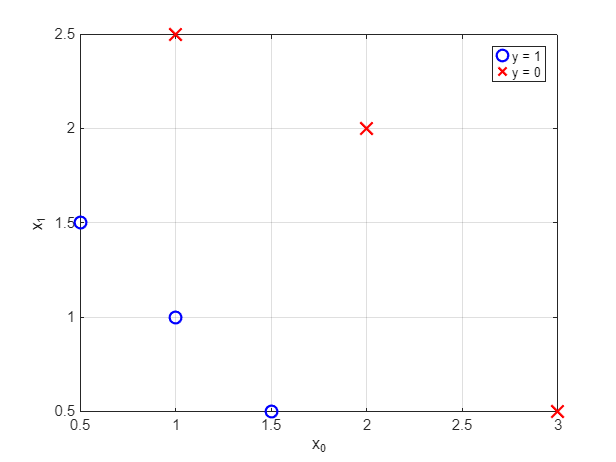

% Plot data set
figure;
hBinaryScatter(X_train_2, y_train_2,{'o','x'},{'b','r'},8);
legend('y = 1','','','y = 0','','','Location','northeast');
xlabel('x_0');
ylabel('x_1');
grid on;

### Cost Function


$$J(\mathbf{w},b) = \frac{1}{m} \sum_{i=1}^{m} L \left( f_{\mathbf{w},b} (\mathbf{x}^{(i)}), y^{(i)}  \right) = -\frac{1}{m} \sum_{i=1}^{m} \bigg( \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) + y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg)$$


where $m$ is the number of training samples. Moreover,

$ f_{\mathbf{w},b}(\mathbf{x}^{(i)}) = g(z^{(i)}) = g(\mathbf{x}^{(i)}\mathbf{w}+b)$, where $g(\mathbf{x}^{(i)}\mathbf{w}+b) = \frac{1}{1 + e^{-\mathbf{x}^{(i)}\mathbf{w}+b}}$

function J = computeLogisticRegressionCost(X, y, w, b)
    % Arguments:
    % X (m,n) : Data, m examples with n features
    % y (m,1) : Target values
    % w (n,1) : model weights
    % b (1,1) : model bias
    m = size(X,1);
    fwb = zeros(m,1);
    J_tmp = 0;
    
    for i = 1:m
        z = X(i,:)*w + b;
        fwb(i) = ( 1/(1+exp(-z)) );
        
        J_tmp = J_tmp + ( (1-y(i))*log(1-fwb(i)) + y(i)*log(fwb(i)) );
    end
    J = -(1/m)*J_tmp;
end

Test the implemented of the cost function, (**Expected output**: 0.3668667864055175)

expected_val = 0.3668667864055175;
w_tmp = [1 1].';
b_tmp = -3;
J = computeLogisticRegressionCost(X_train_2, y_train_2, w_tmp, b_tmp);
fprintf('Cost (J): %.10G\n', J);

Cost (J): 0.3668667864


fprintf('Squared Error (actual vs expected): %.8G\n', (J-expected_val)^2);

Squared Error (actual vs expected): 1.2325952E-32


### Example

Now since we tested the logistic regression cost function, we can examine the cost function output for different $\mathbf{w}$ and $b$.

Let's plot the decision boundary for $w_0=1$, $w_1=1$, $b = -3$ (shown in magenta), $x_0 + x_1 - 3 = 0$

 and $w_0=1$, $w_1=1$, $b = -4$ (shown in cyan), $x_0 + x_1 - 4 = 0$.

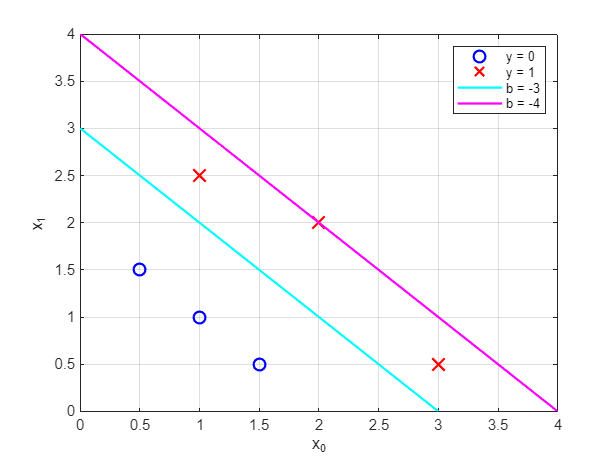

x0 = linspace(0,4);

figure;
hBinaryScatter(X_train_2,y_train_2,{'o','x'},{'b','r'}, 8);
hold on;
plot(x0,3-x0,'c','LineWidth',1.5);
plot(x0,4-x0,'m','LineWidth',1.5);
legend('y = 0','','','y = 1','','','b = -3','b = -4','Location','northeast');
xlabel('x_0');
ylabel('x_1');
grid on;
hold off;
ylim([0 4])

We can see from the above plot that $b=-4$ is a worse model for training data. Let's examine if the loss function reflects this characteristics.

J1 = computeLogisticRegressionCost(X_train_2, y_train_2, [1 1].', -3);
fprintf('Cost for b = -3 (J): %.10G\n', J1);

Cost for b = -3 (J): 0.3668667864


J2 = computeLogisticRegressionCost(X_train_2, y_train_2, [1 1].', -4);
fprintf('Cost for b = -4 (J): %.10G\n', J2);

Cost for b = -4 (J): 0.5036808637


We can see from the above results that the cost function behaves as expected, where the cost function for $b = -4$ case is higher than $b = -3$ case.

## Gradient Descent Implementation

We will take a look at how to find a good choice for the parameters $\mathbf{w}$ and $b$ using gradient descent (GD). The objective could be summarized as follows:

- Find $\mathbf{w}$, $b$

- Given new input ($\mathbf{x}$), that outputs $f_{\mathbf{w},b}(\mathbf{x}) = \frac{1}{1+e^{-(\mathbf{xw}+b)}}$

- Then, model make a prediction $P(y=1 ~ | ~ \mathbf{x};\mathbf{w},b)$

- In the mean time, the algorithm will try to minimizing the cost function ($J(\mathbf{w},b)$) to increase the prediction quality.


$$J(\mathbf{w},b) = \frac{1}{m} \sum_{i=1}^{m} L \left( f_{\mathbf{w},b} (\mathbf{x}^{(i)}), y^{(i)}  \right) = -\frac{1}{m} \sum_{i=1}^{m} \bigg( y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) + \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg)$$


- If we want to minimize the cost function $J(\mathbf{w},b)$, we will use the usual GD algorithm:

repeat {


$$w_j = w_j - \alpha\frac{\partial J(\mathbf{w},b)}{\partial w_j}$$



$$b = b - \alpha\frac{\partial J(\mathbf{w},b)}{\partial b}$$


}

You repetively update the parameters $\mathbf{w}$ and $b$ based on the derivative of the cost function, $J(\mathbf{w},b)$, with respect to the parameters. Let's calculate the terms $\frac{\partial J(\mathbf{w},b)}{\partial w_j}$ and $\frac{\partial J(\mathbf{w},b)}{\partial b}$ to implement the GD algorithm:


$$\frac{\partial J(\mathbf{w},b)}{\partial w_j}

= \frac{\partial}{\partial w_j} \bigg( -\frac{1}{m} \sum_{i=1}^{m} \bigg( y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) + \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg) \bigg) \\

= -\frac{1}{m} \sum_{i=1}^{m} \bigg( \frac{\partial}{\partial w_j} \left( y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \right) + \frac{\partial}{\partial w_j} \left( \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \right) \bigg).$$


1) Let's focus on the first term of the sum,

 
$$\frac{\partial}{\partial w_j} \bigg( y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg)

= y^{(i)}  \frac{\partial}{\partial w_j} \bigg( \log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg)

= y^{(i)} \bigg( \frac{\frac{\partial}{\partial w_j}f_{\mathbf{w},b}(\mathbf{x}^{(i)})}{f_{\mathbf{w},b}(\mathbf{x}^{(i)})} \bigg),$$


where we know that

$\frac{\partial}{\partial w_j} \bigg( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \bigg) 

= x_j^{(i)} \cdot f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) \big( 1-f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) \big)$, where the proof is provided in Appendix 1.

Hence,

 
$$\frac{\partial}{\partial w_j} \bigg( y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg)

= y^{(i)} \bigg( \frac{\frac{\partial}{\partial w_j}f_{\mathbf{w},b}(\mathbf{x}^{(i)})}{f_{\mathbf{w},b}(\mathbf{x}^{(i)})} \bigg)

=  y^{(i)} \bigg( \frac{x_j^{(i)} \cdot f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) \big( 1-f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) \big)}{f_{\mathbf{w},b}(\mathbf{x}^{(i)})} \bigg)

= y^{(i)} \bigg( x_j^{(i)} \cdot \big( 1-f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) \big) \bigg) \quad \#$$


2) Let's focus on the second term of the sum,


$$\frac{\partial}{\partial w_j} \bigg( \left(1-y^{(i)}\right) \log\left( 1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg)
$$


## Appendix

### 1 - Derivative of the sigmoid function with weights and a bias

As a direct consequence of the Appendix 2. We can infer the following:


$$\frac{\partial}{\partial w_j}\left( f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \right) 

= \frac{\partial}{\partial w_j}\left( \frac{1}{1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}} \right)

= \frac{\partial}{\partial w_j}\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-1} \\

= -\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot \frac{\partial}{\partial w_j}\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)

= -\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot \left( \frac{\partial}{\partial w_j}\big( -(\mathbf{x}^{(i)}\mathbf{w}+b) \big) \cdot e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right) \\

= -\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \cdot \bigg( \frac{\partial}{\partial w_j}\big( -\left( x_1^{(i)}w_1+\cdots+x_j^{(i)}w_j+\cdots+x_n^{(i)}w_n \right) \big) \bigg) \\

=  -\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}  \cdot \left( -x_j^{(i)} \right) \\

= \left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot \left( e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} +1-1\right)  \cdot \left( x_j^{(i)} \right) \\

=  x_j^{(i)}\frac{\left( e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} +1-1\right)}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{2}}

=  x_j^{(i)}\frac{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}-1\right)}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{2}}

= x_j^{(i)}\frac{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{2}} - x_j^{(i)}\frac{1}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{2}} \quad ,$$


Therefore,


$$\frac{\partial}{\partial w_j}\left( f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \right)

= \frac{\partial}{\partial w_j}\left( \frac{1}{1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}} \right) \\

= \frac{x_j^{(i)}}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}\right)} \bigg( 1 - \frac{1}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}\right)} \bigg)

=   x_j^{(i)} \cdot f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \cdot \big( 1- f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \big) \quad \#$$


### 2 - Derivative of the sigmoid function

In AI/ML area, the sigmoid function is defined as $\sigma(x) = \frac{1}{1+e^{-x}}$. Derivative of the sigmoid function is crucial for computing the updating the parameters in GD algorithm. Accordingly, in this section we will derive the derivative expression of the sigmoid function.


$$\frac{\text{d}}{\text{d}x}\sigma(x) =  \frac{\text{d}}{\text{d}x} \frac{1}{\left(1+e^{-x}\right)} = \frac{\text{d}}{\text{d}x} \left( 1+e^{-x} \right)^{-1} = -\left( 1+e^{-x} \right)^{-2}\frac{\text{d}}{\text{d}x} \left( 1+e^{-x} \right) \\
=  -\left( 1+e^{-x} \right)^{-2}\frac{\text{d}}{\text{d}x} \left( 1+e^{-x} \right) = -\left( 1+e^{-x} \right)^{-2}\left( -e^{-x} \right) \quad ,$$


Therefore,


$$\frac{\text{d}}{\text{d}x}\sigma(x) = -\left( 1+e^{-x} \right)^{-2}\left( -e^{-x} \right) = \left( 1+e^{-x} \right)^{-2}\left( e^{-x} +1-1 \right) = \frac{\left(1+e^{-x}\right)-1}{ \left( 1+e^{-x} \right)^{2} } \\
= \frac{1}{ \left( 1+e^{-x} \right)}  - \frac{1}{\left( 1+e^{-x} \right)^{2}} = \frac{1}{ \left( 1+e^{-x} \right)} \bigg( 1-\frac{1}{\left( 1+e^{-x} \right)} \bigg) \quad ,$$


Finally,


$$\frac{\text{d}}{\text{d}x}\sigma(x) = \sigma(x) \big( 1-\sigma(x) \big) \quad \#$$
